# Mapping between Martini and Patchy Models

We want to be able to do a sort of table lookup of SASA and dimer PMF parameters that is capable of kicking back the closest set of Martini models, and we also want the (simpler) forward mapping where you pick a Martini chemistry and get back the SASA and dimer PMF parameters associated with it.

addpath('helper_fcns');

## Mapping of single letter SC chemistry to three letter chemistry (and back?)

In Bryce's chemistries, we denote DXXX, where each letter stands for a single amino acid; this is different from Martini, in which the amino acids are denoted by three letters eg f vs PHE. We define a mapping from one to the other to make computations simpler.

letterDict = containers.Map;
letterDict('d') = 'PAS';
letterDict('g') = 'GLY';
letterDict('a') = 'ALA';
letterDict('v') = 'VAL';
%letterDict('c') = 'CYS';
%letterDict('q') = 'GLN';
%letterDict('h') = 'HIS';
letterDict('i') = 'ILE';
letterDict('l') = 'LEU';
letterDict('m') = 'MET';
letterDict('f') = 'PHE';
%letterDict('p') = 'PRO';
%letterDict('s') = 'SER';
%letterDict('t') = 'THR';
letterDict('w') = 'TRP';
letterDict('y') = 'TYR';
letterDict('e') = 'GLU';
%letterDict('n') = 'ASN';
%see also helper_fcns/dxxxTo3list

**Example**

dfagChem = dxxxTo3list('dfag-ndi',letterDict)

dfagChem =     'PAS'    'PHE'    'ALA'    'GLY'


dfagChemNoCore = dxxxTo3list('dfag',letterDict)

dfagChemNoCore =     'PAS'    'PHE'    'ALA'    'GLY'


## SASA Computation

Each chemistry has  an associated SASA (LJ sigma $\sigma_{SC}$) computed as,


$$r_R^{\textrm{SASA}} = \left( \frac{\langle S_R \rangle}{4 \pi}\right)^{1/2}$$



$$\sigma_R^\textrm{SASA} = \frac{\sigma_R}{\langle S_R \rangle} r_R^\textrm{SASA}$$



$$V_R^\textrm{SASA} = \frac{4}{3}\pi \left( r_R^{\textrm{SASA}}\right)^3$$



$$\sigma_R^V = \frac{\sigma_R^\textrm{SASA}}{r_R^\textrm{SASA}}V_R^\textrm{SASA}$$



$$V_{SC} = \sum_R V_R^\textrm{SASA}$$



$$\sigma_{V_{SC}} = \left( \sum_R \left(\sigma_R^V\right)^2\right)^{1/2}$$



$$\sigma_{SC} = 2 \left( \frac{3}{4\pi} V_{SC}\right) ^{1/3}$$



$$\sigma_{\sigma_{SC}} = \frac{\sigma_{V_{SC}}}{V_{SC}} \sigma_{SC}$$


where $\langle S_R \rangle$ is the mean of the solvent accessible surface area of amino acid *R*, $r_R^\textrm{SASA}$ is the radius of a sphere with that surface area, $\sigma_R$ is the standard deviation of the SASA, $\sigma_R^\textrm{SASA}$ is the percent error in the radius, $V_R^{\textrm{SASA}}$ is the volume of a sphere with equivalent radius, $\sigma_R^V$ is the percent error in the volume, $V_{SC}$ is the volume of a set of side chains added together, and $\sigma_{SC}$ is twice the radius of a sphere with that volume.

Check "helper_fcns/computeSasaSig.m".

**Example**

basefolder = '/home/rachael/';
fpath = [basefolder 'cluster/data/mansbac2/coarsegraining/sasaCalcs'];
chem = 'dfag';
chemlist = dxxxTo3list(chem,letterDict);
fnames = {};
for c = 1:length(chemlist)
   fnames{c} = [fpath '/' chemlist{c} '/4_sasa/' chemlist{c} 'sasa.xvg']; 
end
[sigmaDFAG,ssigmaDFAG] = computeSasaSig(fnames);
fprintf('LJ sigma is %f +/- %f',sigmaDFAG,ssigmaDFAG);

LJ sigma is 1.376560 +/- 0.049659

**Largest SC**

fpath = [basefolder 'cluster/data/mansbac2/coarsegraining/sasaCalcs'];
chem = 'dwww';
chemlist = dxxxTo3list(chem,letterDict);
fnames = {};
for c = 1:length(chemlist)
   fnames{c} = [fpath '/' chemlist{c} '/4_sasa/' chemlist{c} 'sasa.xvg']; 
end
[sigmaDFAG,ssigmaDFAG] = computeSasaSig(fnames);
fprintf('LJ sigma is %f +/- %f',sigmaDFAG,ssigmaDFAG);

LJ sigma is 1.625770 +/- 0.063540

**Smallest SC**

fpath = [basefolder 'cluster/data/mansbac2/coarsegraining/sasaCalcs'];
chem = 'daaa';
chemlist = dxxxTo3list(chem,letterDict);
fnames = {};
for c = 1:length(chemlist)
   fnames{c} = [fpath '/' chemlist{c} '/4_sasa/' chemlist{c} 'sasa.xvg']; 
end
[sigmaDFAG,ssigmaDFAG] = computeSasaSig(fnames);
fprintf('LJ sigma is %f +/- %f',sigmaDFAG,ssigmaDFAG);

LJ sigma is 1.245621 +/- 0.032281

**Compute minimum and maximum SASAs**

allSCs = {'ALA','ASN','CYS','GLN','GLU','GLY','HIS','ILE','LEU','MET','PAS','PHE','PRO','SER','THR','TRP','TYR','VAL'};
singleSASAs = zeros(length(allSCs),1);
for ri = 1:length(allSCs)
    fname = [fpath '/' allSCs{ri} '/4_sasa/' allSCs{ri} 'sasa.xvg'];
   sasa = importdata(fname,' ',23);
   sasa = sasa.data(:,2);
   msasa = mean(sasa);  
   rsasa = sqrt(msasa/(4*pi));
   singleSASAs(ri) = rsasa;
end

## Dimer PMF calculation

## Improved Estimates from PMF calculations

We have now performed dimer PMFs for the stripped NDI and PDI cores as used in Bryce's paper.  Let us compute the overall change in free energy for each one and check that the difference between them makes sense with the earlier calculations.

Don't forget to remove the entropic contribution!

**NDI Cores**

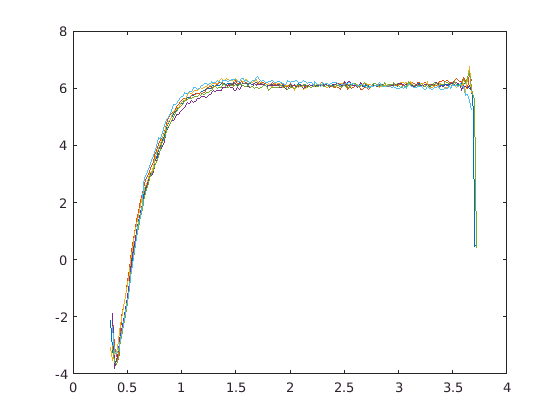

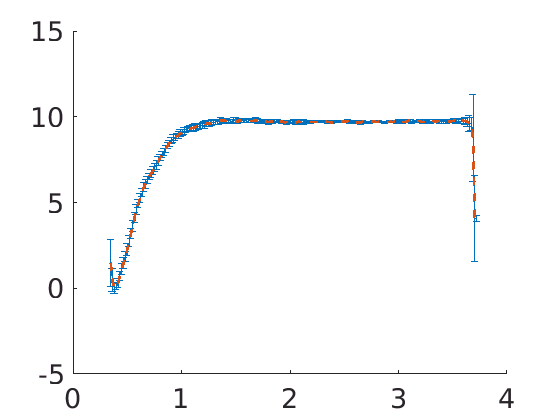

addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/model_assessment');
addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/patchy_particles/helper_functions');
wdirb = '/home/rachael/cluster/scratch/ramansbach/corePMFs/NDI';
%minmaxxs = zeros(6,2);
tstart = 1000;
tinterval = 3800;
tend = 20000;
remove_entropic = 1;
wdir = [wdirb '/5_umbrella'];
[profNDI,errsNDI] = run_block_PMFs(wdir,tstart,tinterval,tend,remove_entropic,[2 3.5 2 3.5 2 3.5 2 3.5 2 3.5]);

**PDI Cores**

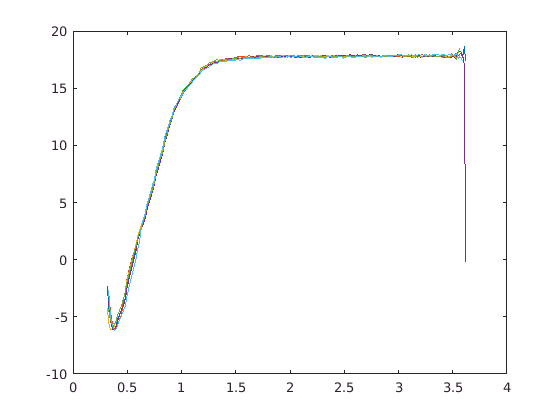

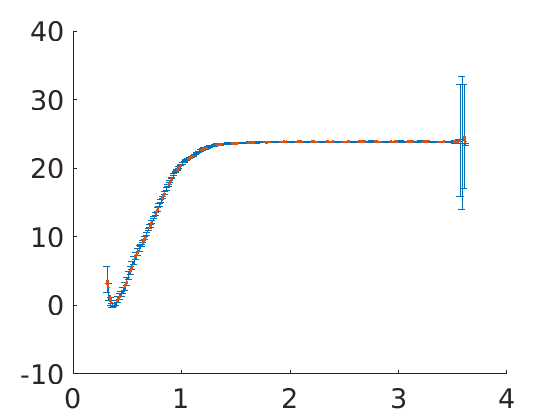

addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/model_assessment');
addpath('/home/rachael/Analysis_and_run_code/analysis/coarsegraining/patchy_particles/helper_functions');
wdirb = '/home/rachael/cluster/scratch/ramansbach/corePMFs/PDI';
%minmaxxs = zeros(6,2);
tstart = 1000;
tinterval = 3800;
tend = 20000;
remove_entropic = 1;
wdir = [wdirb '/5_umbrella'];
[profPDI,errsPDI] = run_block_PMFs(wdir,tstart,tinterval,tend,remove_entropic,[2 3.5 2 3.5 2 3.5 2 3.5 2 3.5]);

All right, this looks pretty good, so now let's estimate the drop for each one.

Take the mean over 2 - 3.5 and subtract the minimum.

Then the error in the maximum (mean over 2-3.5) is the sum-squared-error/number of points

And there's just one error associated with the minimum.

Make it a little easier on yourself and just pick delta F(3 nm) and subtract the minimum and sum the two errors.

minNDI = min(profNDI(:,2));
eminNDI = errsNDI(profNDI(:,2)==min(profNDI(:,2)));
maxNDI = profNDI(abs(profNDI(:,1)-3)==min(abs(profNDI(:,1)-3)),2);
emaxNDI = errsNDI(abs(profNDI(:,1)-3)==min(abs(profNDI(:,1)-3)));
dFNDI = maxNDI - minNDI;
edFNDI = sqrt(eminNDI^2+emaxNDI^2);

minPDI = min(profPDI(:,2));
eminPDI = errsPDI(profPDI(:,2)==min(profPDI(:,2)));
maxPDI = profPDI(abs(profPDI(:,1)-3)==min(abs(profPDI(:,1)-3)),2);
emaxPDI = errsPDI(abs(profPDI(:,1)-3)==min(abs(profPDI(:,1)-3)));
dFPDI = maxPDI - minPDI;
edFPDI = sqrt(eminPDI^2+emaxPDI^2);

ddFcores = dFPDI - dFNDI;
eddFcores = sqrt(edFNDI^2+edFPDI^2);

fprintf('dF for NDI cores is %f +/- %f\n',dFNDI,edFNDI);

dF for NDI cores is 9.676625 +/- 0.317810


fprintf('dF for PDI cores is %f +/- %f\n',dFPDI,edFPDI);

dF for PDI cores is 23.892868 +/- 0.253846


fprintf('Difference in core dFs: %f +/- %f\n',ddFcores,eddFcores);

Difference in core dFs: 14.216243 +/- 0.406744


For the dimer PMF calculation to obtain the $\epsilon_{SC}$ parameter, we have Bryce's predictions for DXXX chemistries with PDI cores and for those with NDI cores.  These predictions vary slightly, so allow them to define a range of PMF values that are approximately reasonable.  The PDI and NDI cores have free energy changes gotten from isolated dimer PMF calculations (see 4_4_18_wing_free_energies) of


$$\Delta F_\textrm{NDI} = 8.5 \pm 0.2 \textrm{ } k_B T$$



$$\Delta F_\textrm{PDI} = 22.9 \pm 0.2 \textrm{ } k_B T,$$


where the errors are estimated from block averaging and sum-square-of-two errors (see again 4_4_18_wing_free_energies).

dFndi = -9.7;
sdFndi = 0.3;
dFpdi = -23.9;
sdFpdi = 0.3;

Using these, we may compute the PMF range for a given chemistry by subtracting off the core free energy change from the predictions of Bryce's model.

Uncertainty bounds are 3$k_B T$ for predictions in Bryce's model!

**Example**

predData = 'predictions.csv';
predictions = importdata(predData);
preds = predictions.data;
predsNDI = preds(1:2:end,1);
predsPDI = preds(2:2:end,1);
chemsndi = predictions.textdata(2:2:end,1);
chemspdi = predictions.textdata(3:2:end,1);
% remove any chemistry that isn't trustworthy
chems = {};
pN = [];
pP = [];
nxt = 1;
for c = 1:length(chemsndi)
    dxxx = chemsndi{c};
    dxxx = strsplit(dxxx,'-');
    dxxx = dxxx(1);
    dxxx = char(dxxx);
    trusted = true;
    for r = 1:length(dxxx)
        if ~isKey(letterDict,dxxx(r))
            trusted = false;
        end
        for r = 2:length(dxxx)
            if dxxx(r) == 'd'
               trusted = false; 
            end
        end
    end
    if trusted
        chems{nxt} = dxxx;
        pN = [pN; predsNDI(c,:)];
        pP = [pP; predsPDI(c,:)];
        nxt = nxt + 1;
    end
end
predsNDI = pN;
predsPDI = pP;
scFndi = (predsNDI-dFndi)/2;
sscFndi = sqrt(sdFndi^2 + 3^2); %sum-squared-error
scFpdi = (predsPDI-dFpdi)/2;
sscFpdi = sqrt(sdFpdi^2+3^2);
for c = 1:length(chems)
   if chems{c} == 'dfag'
       fprintf('Prediction range is %f +/- %f -- %f +/- %f\n',scFndi(c),sscFndi,scFpdi(c),sscFpdi);
   end
end

Prediction range is 0.715567 +/- 3.014963 -- 0.191311 +/- 3.014963


## Compute Forward Mapping

In fact, we can compute a set of tables to query from all of this.

For each different SC chemistry in the chemlist, compute the SASA and make a full SASA array.

Compute also a 2-column table that is the range of mean predictions (and remember that all means have 3 kT uncertainties on them--but don't use this for the time being).

We can then make a function that finds the closest SASA to a particular query, a function that returns a particular range of nearest SASAs, and a function that queries for all SASA *within* a given range.

We can do the same for a function that queries on the PMF except that it always checks the range (of mean predictions).

**SASA Table **

sasaPredictions = zeros(length(chems),2); %with errors
for c = 1:length(chems)
    fpath = [basefolder 'cluster/data/mansbac2/coarsegraining/sasaCalcs'];
    chem = chems{c};
    chemlist = dxxxTo3list(chem,letterDict);
    fnames = {};
    for r = 1:length(chemlist)
        fnames{r} = [fpath '/' chemlist{r} '/4_sasa/' chemlist{r} 'sasa.xvg'];
    end
    [sigma,ssigma] = computeSasaSig(fnames);
    sasaPredictions(c,:) = [sigma,ssigma];
end

**PMF Range Table**

pmfPredictions = [scFndi scFpdi];
for row = 1:size(pmfPredictions,1)
    r1 = pmfPredictions(row,1);
    r2 = pmfPredictions(row,2);
   if r1 > r2
       pmfPredictions(row,1) = r2;
       pmfPredictions(row,2) = r1;
   end
end

**Example**

Query on Pareto Point 1 with $\epsilon_{SC} = 0.2\textrm{ } k_B T$ and $\sigma_{SC} = 1.5$ nm.

Let's go ahead and do all points for which the query falls into the error bars thereof--define the error reasonably widely, from the computed stddev of the SASA and the 3 kT error in the predictions from Bryce -- actually let's just use the NDI--PDI range because 3kT gets you *a lot*

sasaRange  = [sasaPredictions(:,1)-sasaPredictions(:,2),sasaPredictions(:,1)+sasaPredictions(:,2)];
pmfRange = [mean(pmfPredictions,2)-3,mean(pmfPredictions,2)+3];
eps = -0.2;
sig = 1.5;
[chems1,sasas1,pmfs1,inds1] = findClosestChems(chems,sasaRange,pmfPredictions,sig,eps);

Query on Pareto Point 2 with $\epsilon_{SC} = 0.2\textrm{ } k_B T$ and $\sigma_{SC} = 1.75$ nm.

eps = -0.2;
sig = 1.75;
[chems2,sasas2,pmfs2,inds2] = findClosestChems(chems,sasaRange,pmfPredictions,sig,eps);

Query on Pareto proximal point with $\epsilon_{SC} = 0.2\textrm{ } k_B T$ and $\sigma_{SC} = 1.25$ nm.

eps = -0.2;
sig = 1.25;
[chemse1,sasase1,pmfse1,indse1] = findClosestChems(chems,sasaRange,pmfPredictions,sig,eps);

## Plot of projected Martini chemistries with Pareto frontier

We are going to project down the Pareto frontier and just color it differently based on $\epsilon_A$ values.

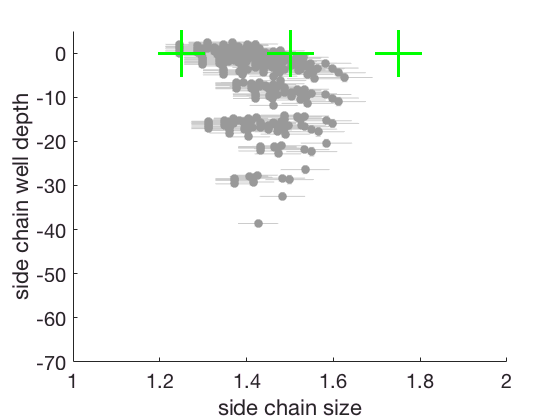

addpath([basefolder '/Analysis_and_run_code/data_visualization']);
figure()
hold on
set(gca,'fontsize',24)
pmfrange = mean(pmfPredictions,2);
pmferrs = pmfPredictions(:,2) - pmfrange;
errorbarxy(sasaPredictions(:,1),pmfrange,sasaPredictions(:,2),pmferrs);
plot(sasaPredictions(:,1),pmfrange,'.','markersize',30,'color',[0.6 0.6 0.6])
ylim([-40 5])
xlim([1 2])
plot([1.25 1.5 1.75],[-0.2 -0.2 -0.2],'g+','markersize',45,'linewidth',3)
%plot(sasaPredictions([find(inds1)],1),pmfrange([find(inds1)]),'rx','markersize',18,'linewidth',2)
%plot(sasaPredictions([find(indse1)],1),pmfrange([find(indse1)]),'rx','markersize',18,'linewidth',2)
% smin1 = min(sasaRange(find(inds1),1));
% smax1 = max(sasaRange(find(inds1),2));
% emin1 = min(pmfPredictions(find(inds1),1));
% emax1 = max(pmfPredictions(find(inds1),2));
% %patch([smin1,smax1,smax1,smin1],[emin1,emin1,emax1,emax1],'c','facealpha',0.7,'edgecolor','none')
% 
% smine1 = min(sasaRange(find(indse1),1));
% smaxe1 = max(sasaRange(find(indse1),2));
% emine1 = min(pmfPredictions(find(indse1),1));
% emaxe1 = max(pmfPredictions(find(indse1),2));
%patch([smine1,smaxe1,smaxe1,smine1],[emine1,emine1,emaxe1,emaxe1],'c','facealpha',0.7,'edgecolor','none')
%ylim([-12 2])
xlabel('side chain size')
ylabel('side chain well depth')